%Cargamos los parametros de la camara despues de obtenerlos de la sesion de
%calibracion
clear all;

ld = load("cameraParams.mat"); %Cargamos los parametros de la camara 
intrinsics = ld.cameraParams.Intrinsics; %Cargamos unicamente los parametros intrinsecos de la camara

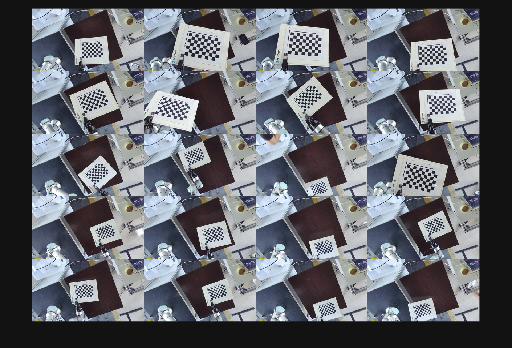

%Cargamos las imagenes que tenemos en la carpeta de de donde estan las fotos con 
% sus respectivas poses y decimos cuantas poses fueron en total 
%(esta es igual al numero de fotos)
numPoses = 20; %Colocamos el numero de fotos que tomamos 
imds = imageDatastore("CAMARA/COBOTPOSES"); %Cargamos todas las fotos tomadas en orden 
montage(imds) %Realiazmos el montaje de las fotos en orden por nombre

squareSize = 0.022; %Colocamos la medidas de los cubos en metros
camExtrinsics(numPoses,1) = rigidtform3d; %Creamos matrices de identidad de 4x4 (con 1 en diagonal)

%Estimamos la transoformada del tablero hacia la camara para cada pose
for i = 1:numPoses
    %Leemos cada imagen y utilizamos los parametros intrinsecos para quitar
    %la distorcion de cada imagen y la guardamos
    calibrationImage = readimage(imds,i);
    undistortedImage = undistortImage(calibrationImage,intrinsics);
    % Estimamos los valores extrinsecos mientras no se lee el tablero de
    % ajedrez, para poder detectar bien el origen del tablero en cada
    % imagen
    [imagePoints, boardSize] = detectCheckerboardPoints(undistortedImage,PartialDetections=false);
    worldPoints = patternWorldPoints("checkerboard",boardSize,squareSize);
    camExtrinsics(i) = estimateExtrinsics(imagePoints,worldPoints,intrinsics);
end


%Cargamos los datos y tabla que contiene las configuraciones de las juntas
%para cada foto
jointConfiguration = load("jntconfig.mat");
jointPositionsDeg = jointConfiguration.TablaDatos;
jointAngles = table2array(jointPositionsDeg); %La volvemos un arreglo

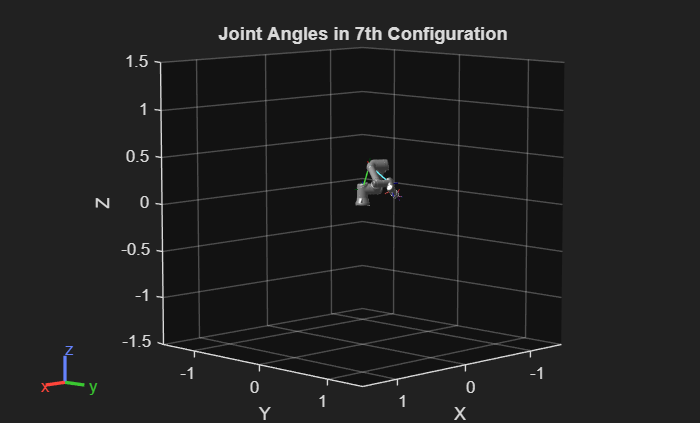

figure
kinova = loadrobot('UniversalUR5e',DataFormat="row");
show(kinova,deg2rad(jointAngles(20,:)));
title("Joint Angles in 7th Configuration")
axis equal
rotate3d("on")

numimgs = length(imds.Files);
camExtrinsics = repmat(rigidtform3d,1,numimgs);

for r = 1:numimgs

    % Load and undistort each calibration image based on precomputed intrinsics.
    fname = fullfile('CAMARA/COBOTPOSES',string(r)+".png");
    checkerboardImage = imread(fname);
    checkerboardImageUndistorted = undistortImage(checkerboardImage,intrinsics);

    % Detect the checkerboard corners, discarding partial detections.
    [imgpts,boardsz] = detectCheckerboardPoints(checkerboardImageUndistorted,PartialDetections=false);

    % Generate world coordinates of checkerboard points based on board size and square size.
    worldpts = patternWorldPoints("checkerboard",boardsz,squareSize);
    
    % Estimate the camera extrinsics (pose) from image points and world points.
    camextrinsics(r) = estimateExtrinsics(imgpts,worldpts,intrinsics);
end


TEndEffectorToBase = repmat(rigidtform3d,1,numimgs);

for r = 1:numimgs
    jointconfig = deg2rad(jointAngles(r,:));
    TEndEffectorToBase(r) = getTransform(kinova,jointconfig,"flange");
end

TCameraToBase = estimateCameraRobotTransform(camextrinsics,TEndEffectorToBase,"stationary-camera");

TWorldToBase = rigidtform3d(TCameraToBase.A*camextrinsics(end).A);
worldpts3d = transformPointsForward(TWorldToBase,[worldpts,zeros(size(worldpts,1),1)]);

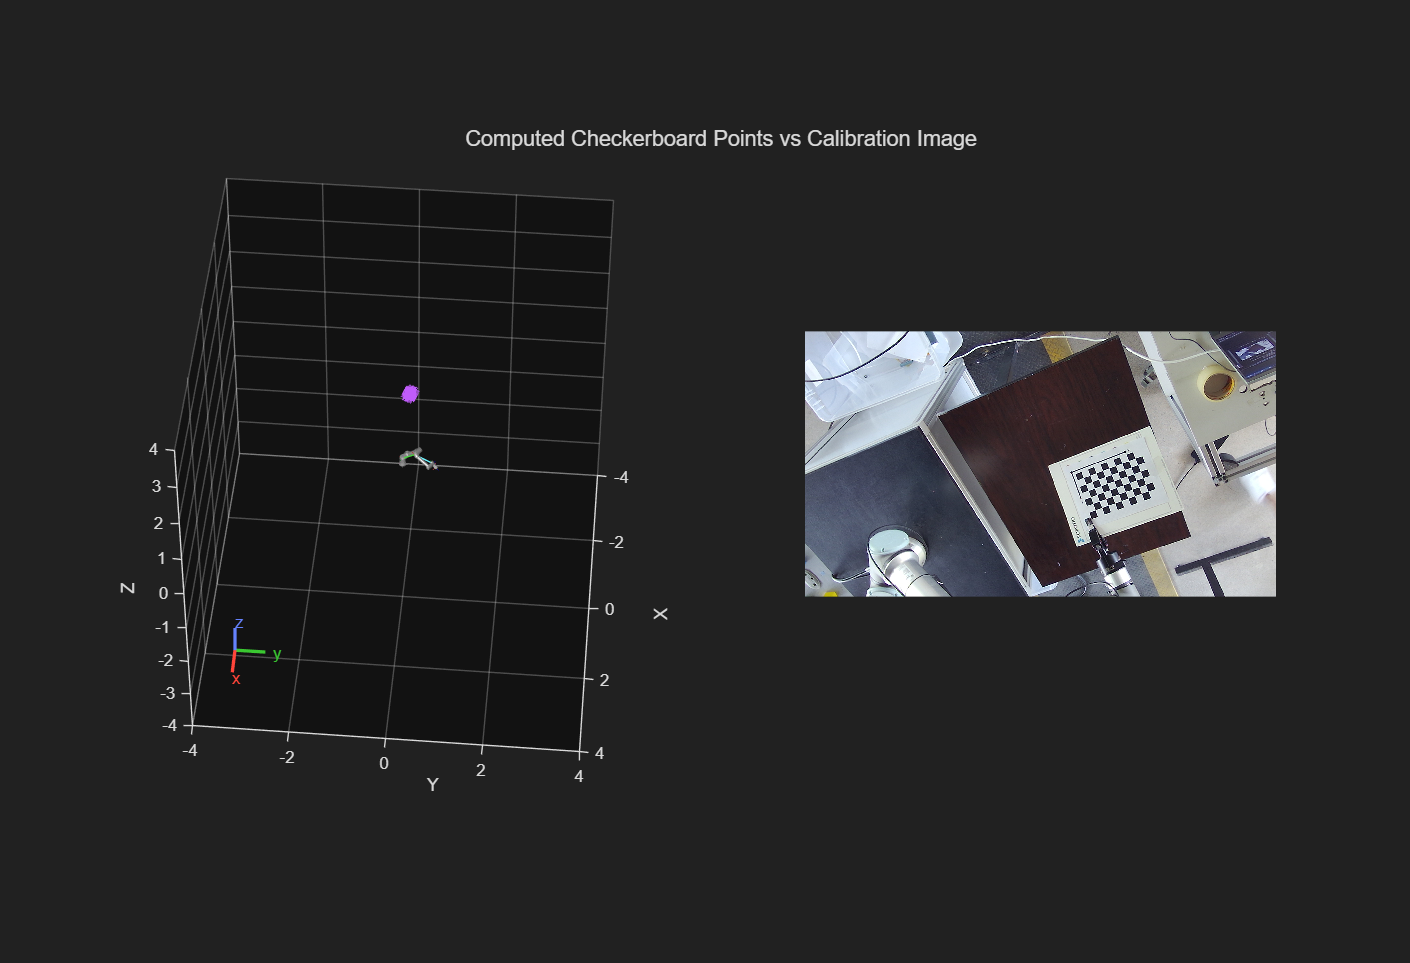

tiledlayout(1,2)
nexttile
show(kinova,deg2rad(jointAngles(r,:)));

rotate3d("on")

hold on
scatter3(worldpts3d(:,1),worldpts3d(:,2),worldpts3d(:,3),'*')
view(95,45)
axis([-4 4 -4 4 -4 4])
hold off
nexttile
imshow("CAMARA/COBOTPOSES/"+string(r)+".png")
sgtitle("Computed Checkerboard Points vs Calibration Image")

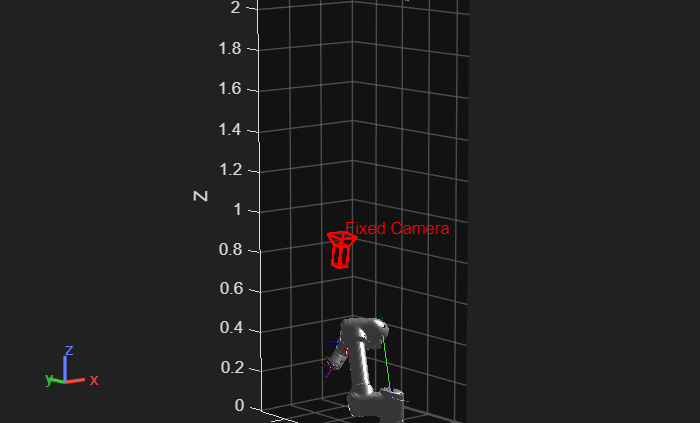

figure
show(kinova,deg2rad(jointAngles(r,:)));

rotate3d("on")

hold on
scatter3(worldpts3d(:,1),worldpts3d(:,2),worldpts3d(:,3),'*')
plotCamera(AbsolutePose=TCameraToBase,Size=0.05,Label="Fixed Camera");
title("Estimated Camera Frame With Respect to Robot Base")
view([-40,10])
zoom(1.5)
axis equal
hold off